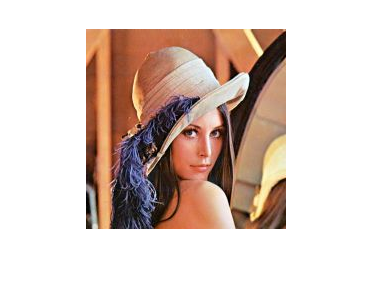

A = imread('lena.jpg');
imshow(A);

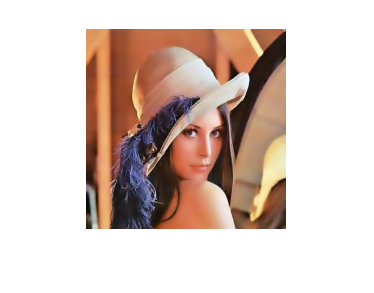

B=imguidedfilter(A);
imshow(B);


A = imread('lena.jpg');
imshow(A);

%%B=imguidedfilter(A);
%%imshow(B);
alpha_t = .01;
N_iter =3;
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only
tic
[T,R] = muGIF(A,A,alpha_t,0,N_iter,mode)  ;
toc

时间已过 2.511006 秒。


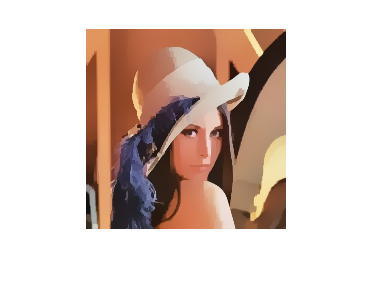

figure;imshow(T,[]);colormap('hot');


load('Indian_pines_corrected.mat');
%b1= indian_pines_corrected(:,:,10);
%[m,n]=size(b1)
%b1_255=mapminmax(b1,0,255)
%X*=（X-Xmin）/(Xmax-Xmin)
indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;
b1= indian255(:,:,10);
b1_3D=zeros(145,145,3);
b1_3D(:,:,1)=b1(:,:);
b1_3D(:,:,2)=b1(:,:);
b1_3D(:,:,3)=b1(:,:);
imshow(b1_3D);%显示白色,error

%B = reshape(indian255,[],200);
%size(B)
%plot(B)
%plot(B(100,:))
%whos A %重看类型
b13D=uint8(b1_3D)

b13D = 145×145×3 uint8 数组
b13D(:,:,1) =

   112   121   123   122   114   104   104   111   115   112   109   107   107   106   101    97    95    94    96   111   112   105   100    99    99    93    90    92    91    97   101   103    95    89    95   106   112   116   111   111   114   119   118   111   107   109   110   108   110   116   121   118   119   122   123   127   124   127   130   130   130   132   136   138   139   135   114   104   114   110   101    94    90    88    89    88    89    90    93    85    83    83    81    83    82    83    84    85    84    84    83    83    83    86    85    87   106   120   114   114   121   123   119   117   115   111   113   119   120   118   116   110   107   102    99    99   102   102   103   125   121   125   121   113   111   110   110   117   124   131   129   123   121   114   112   112   112   113   115   115   112   104   103   103   105
   110   118   121   122   113   108   106   107   111   111   110   107   109   113   1

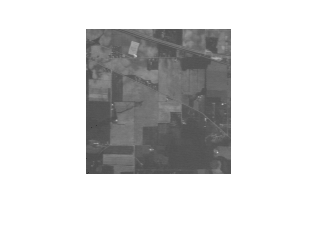

imshow(b13D)  %为何显示灰度图


load('Indian_pines_corrected.mat');
%b1= indian_pines_corrected(:,:,10);
%[m,n]=size(b1)
%b1_255=mapminmax(b1,0,255)
%X*=（X-Xmin）/(Xmax-Xmin)
indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;
b1= indian255(:,:,10);
% b1_3D=zeros(145,145,3);
% b1_3D(:,:,1)=b1(:,:);
% b1_3D(:,:,2)=b1(:,:);
% b1_3D(:,:,3)=b1(:,:);
b11=uint8(b1)

b11 = 145×145 uint8 矩阵
   112   121   123   122   114   104   104   111   115   112   109   107   107   106   101    97    95    94    96   111   112   105   100    99    99    93    90    92    91    97   101   103    95    89    95   106   112   116   111   111   114   119   118   111   107   109   110   108   110   116
   110   118   121   122   113   108   106   107   111   111   110   107   109   113   110   103   100    94   102   113   111   106   103   104   105   100   100   106   105   102    96    93    94   100   101    96    89    92   100   111   113   110   108   112   117   117   112   108   107   109
   111   118   120   119   112   109   108   111   115   116   112   108   107   113   115   111   103    99   110   112   107   108   108   107   107   103   102   102   105   107   105   104   102    97    90    91   101   103    97    90    92   100   110   113   111   108   109   117   117   112
   108   117   118   114   111   108   109   112   114   114   113   111  

imshow(b11);


alpha_t = .001;
N_iter =3;
mode = 2;

tic
[T,R] = muGIF(b11,b11,alpha_t,0,N_iter,mode)  ;
toc

时间已过 1.131071 秒。


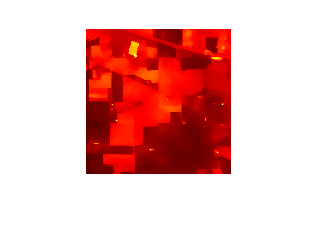

figure;imshow(T,[]);colormap('hot');


imshow(b13D)

alpha_t = .001;
N_iter =3;
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only
tic
[T,R] = muGIF(b13D,b13D,alpha_t,0,N_iter,mode)  ;
toc

时间已过 0.262468 秒。


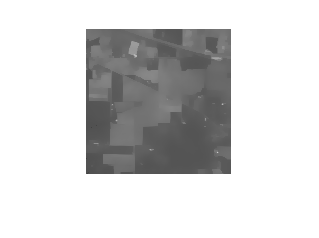

figure;imshow(T,[]);colormap('hot');



BB=imguidedfilter(b13D);
imshow(BB);




%indianB=zeros(145,145,200);
load('Indian_pines_corrected.mat');
indian=indian_pines_corrected;
indian=(indian-minindian)/(maxindian-minindian);

indian255=indian*255;

indianAfterFilterMGIF=zeros(145,145,200);
% for i =1:200
%     %fprintf("i=%d\n",i);
%     indianB(:,:,i)=indian255(:,:,i);
% end
indian255uint8=uint8(indian255);
%figure
%imshow(indianAfterFilterMGIF(:,:,10:12));
%imshow(indianAfterFilterMGIF(:,:,49));

alpha_t = .01;
N_iter =3;
mode = 2;
for i =1:200
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian255uint8(:,:,i),alpha_t,0,N_iter,mode);
end

i=1
i=2
i=3
i=4
i=5
i=6
i=7
i=8
i=9
i=10
i=11
i=12
i=13
i=14
i=15
i=16
i=17
i=18
i=19
i=20
i=21
i=22
i=23
i=24
i=25
i=26
i=27
i=28
i=29
i=30
i=31
i=32
i=33
i=34
i=35
i=36
i=37
i=38
i=39
i=40
i=41
i=42
i=43
i=44
i=45
i=46
i=47
i=48
i=49
i=50
i=51
i=52
i=53
i=54
i=55
i=56
i=57
i=58
i=59
i=60
i=61
i=62
i=63
i=64
i=65
i=66
i=67
i=68
i=69
i=70
i=71
i=72
i=73
i=74
i=75
i=76
i=77
i=78
i=79
i=80
i=81
i=82
i=83
i=84
i=85
i=86
i=87
i=88
i=89
i=90
i=91
i=92
i=93
i=94


%[T,R] = muGIF(indianAfterFilterMGIF(:,:,49),indianAfterFilterMGIF(:,:,49),alpha_t,0,N_iter,mode)  ;
figure;
imshow(indianAfterFilterMGIF(:,:,10),[]);
%imshow(T,[]);
%colormap('hot');

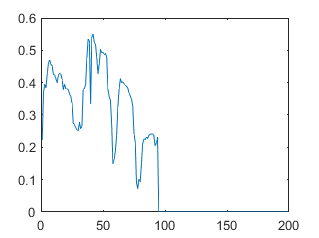


%indianAfterFilterMGIF
B = reshape(indianAfterFilterMGIF,[],200);
C255 = reshape(indian255,[],200);
%size(B)
%plot(B)
plot(B(10,:))

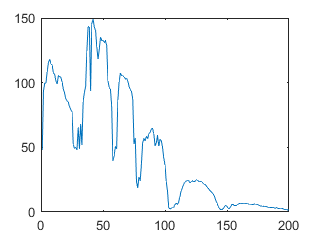

plot(C255(10,:))%绘制曲线

save("indianAfterFilterMGIF010.mat",'indian');


load('Indian_pines_corrected.mat');
%b1= indian_pines_corrected(:,:,10);
%[m,n]=size(b1)
%b1_255=mapminmax(b1,0,255)
%X*=（X-Xmin）/(Xmax-Xmin)
indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;

indian2D = reshape(indian255,[],200);
[coeff, score, latent, TSQUARED] = pca(indian2D);

indian3D = reshape(score,145,145,200);%可能不是用这个，也可能是
indian3D1=indian3D(:,:,1);%显示第一个PC
indian3D1=mapminmax(indian3D1,0,255);
%indian3D255=mapminmax(indian3D,0,255);
indian3D1=uint8(indian3D1);
figure
imshow(indian3D1)


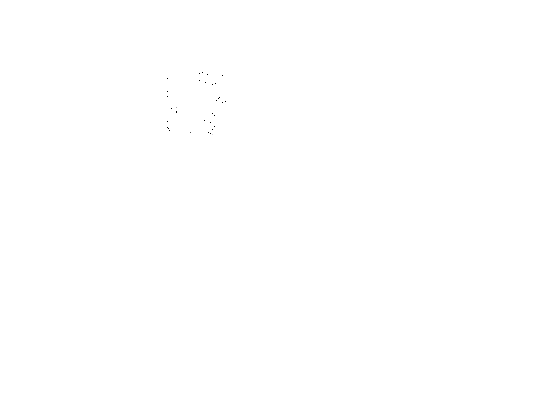


figure
%imshow(indian3D1)

for i = 1:24
    %indian3D = reshape(score,145,145,200);
    indian3D1=indian3D(:,:,i);
    indian3D1=mapminmax(indian3D1,0,255);
    indian3D1=uint8(indian3D1);
    subplot(3,8,i);
    imshow(indian3D1);
end

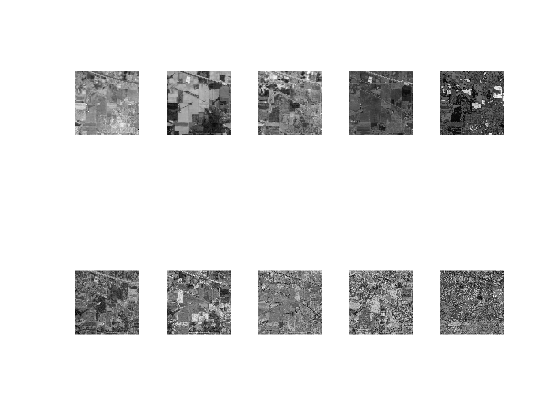


load('Indian_pines_corrected.mat');
%indian=repmat(indian_pines_corrected,1);
indian=indian_pines_corrected;
indian2=zeros(200,145*145);
% 加载样本图像到 30*(64*64)的矩阵中，每一行代表一幅图像
for i=1:200
    image=indian(:,:,i);%(145,145)
    %Image=imresize(image,[64,64]);
    indian2(i,:)=double(reshape(image,1,[]));%reshape(image,1,[])=(1,21025)
end


[coeff, score, latent, TSQUARED] = pca(indian2);%score(200,199)

%coeff(21025,199)
for i=1:24
    Eigenface=reshape(coeff(:,i),[145,145]);
    %figure(i);
    subplot(3,8,i);
    imshow(mat2gray(Eigenface));
end



for i=25:48
    Eigenface=reshape(coeff(:,i),[145,145]);
    %figure(i);
    subplot(3,8,i-24);
    imshow(mat2gray(Eigenface));
end


%indianB=zeros(145,145,200);
load('Indian_pines_corrected.mat');
indian=indian_pines_corrected;
indian=(indian-minindian)/(maxindian-minindian);

indian255=indian*255;

indianAfterFilterMGIF=zeros(145,145,200);
% for i =1:200
%     %fprintf("i=%d\n",i);
%     indianB(:,:,i)=indian255(:,:,i);
% end
indian255uint8=uint8(indian255);
%figure
%imshow(indianAfterFilterMGIF(:,:,10:12));
%imshow(indianAfterFilterMGIF(:,:,49));

alpha_t = .01;
N_iter =3;
mode = 2;
for i =1:200
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian255uint8(:,:,i),alpha_t,0,N_iter,mode);
end
%[T,R] = muGIF(indianAfterFilterMGIF(:,:,49),indianAfterFilterMGIF(:,:,49),alpha_t,0,N_iter,mode)  ;
figure;
imshow(indianAfterFilterMGIF(:,:,10),[]);
%imshow(T,[]);
%colormap('hot');


%indianAfterFilterMGIF
B = reshape(indianAfterFilterMGIF,[],200);
C255 = reshape(indian255,[],200);
%size(B)
%plot(B)
plot(B(10,:))
plot(C255(10,:))%绘制曲线
save("indianAfterFilterMGIF010.mat",'indian');


load('Indian_pines_corrected.mat');

indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;%缩放

indian2D = reshape(indian255,[],200);%145*145*200-->21025*200


[coeff, score, latent, TSQUARED] = pca(indian2D);
indian3D = reshape(score,145,145,200);%是这个,score中存有PC
indian3D1=indian3D(:,:,1);%显示第一个PC

indian3D1=mapminmax(indian3D1,0,255);


indian3DNo1PC1=uint8(indian3D1)
%imshow(indian3DNo1PC1)


load('Indian_pines_corrected.mat');
indian=indian_pines_corrected;
indian=(indian-minindian)/(maxindian-minindian);

indian2552=indian*255;%

indianAfterFilterGIF=zeros(145,145,200);

indian255uint8=uint8(indian2552);%AG都用这个函数可能更好？



alpha_t = .01;
N_iter =3;%
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only

%[T,R] = muGIF(A,A,alpha_t,0,N_iter,mode);

for i =1:200
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DNo1PC1,alpha_t,0,N_iter,mode);
end

save indianAfterFilterMGIFalpha001N3modeOnePC.mat indianAfterFilterMGIF

%muGIF

A = imread('lena.jpg');
imshow(A);
%%B=imguidedfilter(A);
%%imshow(B);
alpha_t = .01;
N_iter =3;
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only
tic
[T,R] = muGIF(A,A,alpha_t,0,N_iter,mode)  ;
toc
figure;imshow(T,[]);colormap('hot');

%muGIF
%将一幅图像进行滤波，之前要添加路径
A = imread('lena.jpg');
imshow(A);
%%B=imguidedfilter(A);
%%imshow(B);
alpha_t = .01;
N_iter =50;%y越大越模糊
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only
tic
[T,R] = muGIF(A,A,alpha_t,0,N_iter,mode);
toc
figure;imshow(T,[]);colormap('hot');


load('Indian_pines_corrected.mat');

indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;%缩放

indian2D = reshape(indian255,[],200);%145*145*200-->21025*200


[coeff, score, latent, TSQUARED] = pca(indian2D);
indian3D = reshape(score,145,145,200);%是这个,score中存有PC
indian3D1=indian3D(:,:,1);%显示第一个PC

indian3D1=mapminmax(indian3D1,0,255);


indian3DNo1PC1=uint8(indian3D1)
%imshow(indian3DNo1PC1)


load('Indian_pines_corrected.mat');
indian=indian_pines_corrected;
indian=(indian-minindian)/(maxindian-minindian);

indian2552=indian*255;%预处理数据

indianAfterFilterGIF=zeros(145,145,200);

indian255uint8=uint8(indian2552);%AG都用这个函数可能更好？



alpha_t = .01;
N_iter =3;%y越大越模糊
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only

%[T,R] = muGIF(A,A,alpha_t,0,N_iter,mode);

for i =1:200
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DNo1PC1,alpha_t,0,N_iter,mode);
end

save indianAfterFilterMGIFalpha001N3modeOnePC.mat indianAfterFilterMGIF

%MuGIF
%按距离密度将此分组5个PC作为导向图保存滤波数据
%1-25 26-50 51-75 76-100 101-200
%indian3DNo1-5DDPC
%将所有波段都进行滤波之后重新得到一个新的数据集
%indianB=zeros(145,145,200);
load('Indian_pines_corrected.mat');

indian=repmat(indian_pines_corrected,1);
maxindian=max(max(max(indian)));
minindian=min(min(min(indian)));
indian=(indian-minindian)/(maxindian-minindian);
indian255=indian*255;%缩放
indian255uint8=uint8(indian255);
indian2D = reshape(indian255,[],200);%145*145*200-->21025*200


indianAfterFilterMGIF=zeros(145,145,200);



%获取四个PC
indian2D1=indian2D(:,1:25)
indian2D2=indian2D(:,26:50)
indian2D3=indian2D(:,51:75)
indian2D4=indian2D(:,76:100)
indian2D5=indian2D(:,101:200)



[coeff, score, latent, TSQUARED] = pca(indian2D1);%改变这里输出四个分组的主成分
indian3D = reshape(score,145,145,25);%是这个
indian3DPC1=indian3D(:,:,1);%显示第一个PC
indian3DPC1=mapminmax(indian3DPC1,0,255);

[coeff, score, latent, TSQUARED] = pca(indian2D2);%改变这里输出四个分组的主成分
indian3D = reshape(score,145,145,25);%是这个
indian3DPC2=indian3D(:,:,1);%显示第一个PC
indian3DPC2=mapminmax(indian3DPC2,0,255);

[coeff, score, latent, TSQUARED] = pca(indian2D3);%改变这里输出四个分组的主成分
indian3D = reshape(score,145,145,25);%是这个
indian3DPC3=indian3D(:,:,1);%显示第一个PC
indian3DPC3=mapminmax(indian3DPC3,0,255);

[coeff, score, latent, TSQUARED] = pca(indian2D4);%改变这里输出四个分组的主成分
indian3D = reshape(score,145,145,25);%是这个
indian3DPC4=indian3D(:,:,1);%显示第一个PC
indian3DPC4=mapminmax(indian3DPC4,0,255);

[coeff, score, latent, TSQUARED] = pca(indian2D5);%改变这里输出四个分组的主成分
indian3D = reshape(score,145,145,100);%是这个
indian3DPC5=indian3D(:,:,1);%显示第一个PC
indian3DPC5=mapminmax(indian3DPC5,0,255);

indian3DPC1=uint8(indian3DPC1);
indian3DPC2=uint8(indian3DPC2);
indian3DPC3=uint8(indian3DPC3);
indian3DPC4=uint8(indian3DPC4);
indian3DPC5=uint8(indian3DPC5);

alpha_t = .01;
N_iter =3;%y越大越模糊
mode = 2; %mode = 0 dynamic/dynamic 
          % mode = 1; % static/dynamic
          % mode = 2; % dynamic only

for i =1:25
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DPC1,alpha_t,0,N_iter,mode);
    %[indianAfterFilterGIF(:,:,i)]=imguidedfilter(indian255uint8(:,:,i),indian3DPC1);
end

for i =26:50
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DPC2,alpha_t,0,N_iter,mode);
    %[indianAfterFilterGIF(:,:,i)]=imguidedfilter(indian255uint8(:,:,i),indian3DPC2);
end

for i =51:75
    fprintf("i=%d\n",i);
    [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DPC3,alpha_t,0,N_iter,mode);
    %[indianAfterFilterGIF(:,:,i)]=imguidedfilter(indian255uint8(:,:,i),indian3DPC3);
end

for i =76:100
    fprintf("i=%d\n",i);
     [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DPC4,alpha_t,0,N_iter,mode);
    %[indianAfterFilterGIF(:,:,i)]=imguidedfilter(indian255uint8(:,:,i),indian3DPC4);
end

for i =101:200
    fprintf("i=%d\n",i);
     [indianAfterFilterMGIF(:,:,i),R]=muGIF(indian255uint8(:,:,i),indian3DPC5,alpha_t,0,N_iter,mode);
    %[indianAfterFilterGIF(:,:,i)]=imguidedfilter(indian255uint8(:,:,i),indian3DPC5);
end





save indianAfterFilterMGIFalpha001N3modeOne5PCDDGrouped.mat indianAfterFilterMGIF
